**Sistema LTV instabile con autovalori negativi**

Studiamo il sistema dinamico:


$$\dot{x} \left(t\right)=A\left(t\right)x\left(t\right),$$


con


$$A\left(t\right)=\left\lbrack \begin{array}{cc}
-1 & q\left(t\right)\\
0 & -1
\end{array}\right\rbrack$$


dove $q\left(t\right)=e^{2t}$.

Gli autovalori di A(t) sono sempre -1 e -1 (parte reale negativa).

*Derivazione analitica*

Le equazioni scalari soluzione dell'equazione differenziale sono:


$$\begin{array}{l}
\dot{x_2 } \;\left(t\right)=-x_2 \left(t\right)\\
\dot{x_1 } \;\left(t\right)=-x_1 \left(t\right)+q\left(t\right){\;x}_2 \left(t\right)
\end{array}$$


da cui


$$x_2 \;\left(t\right)=x_2 \left(0\right)e^{-t}$$


e sostituendo 


$$\dot{x_1 } \;\left(t\right)=-x_1 \left(t\right)+e^{2t} x_2 \left(0\right)e^{-t} =$$

$$-x_1 \left(t\right)+x_2 \left(0\right)e^t$$


 la cui soluzione risulta


$$x_1 \left(t\right)=x_1 \left(0\right)e^{-t} +\frac{1}{2}x_2 \left(0\right)\;*\left(\exp \left(t\right)-\exp \left(-t\right)\right)$$


e, per t -> Inf, il termine dominante è (x2(0)/2)*exp(t) -> crescita esponenziale -> instabilità.

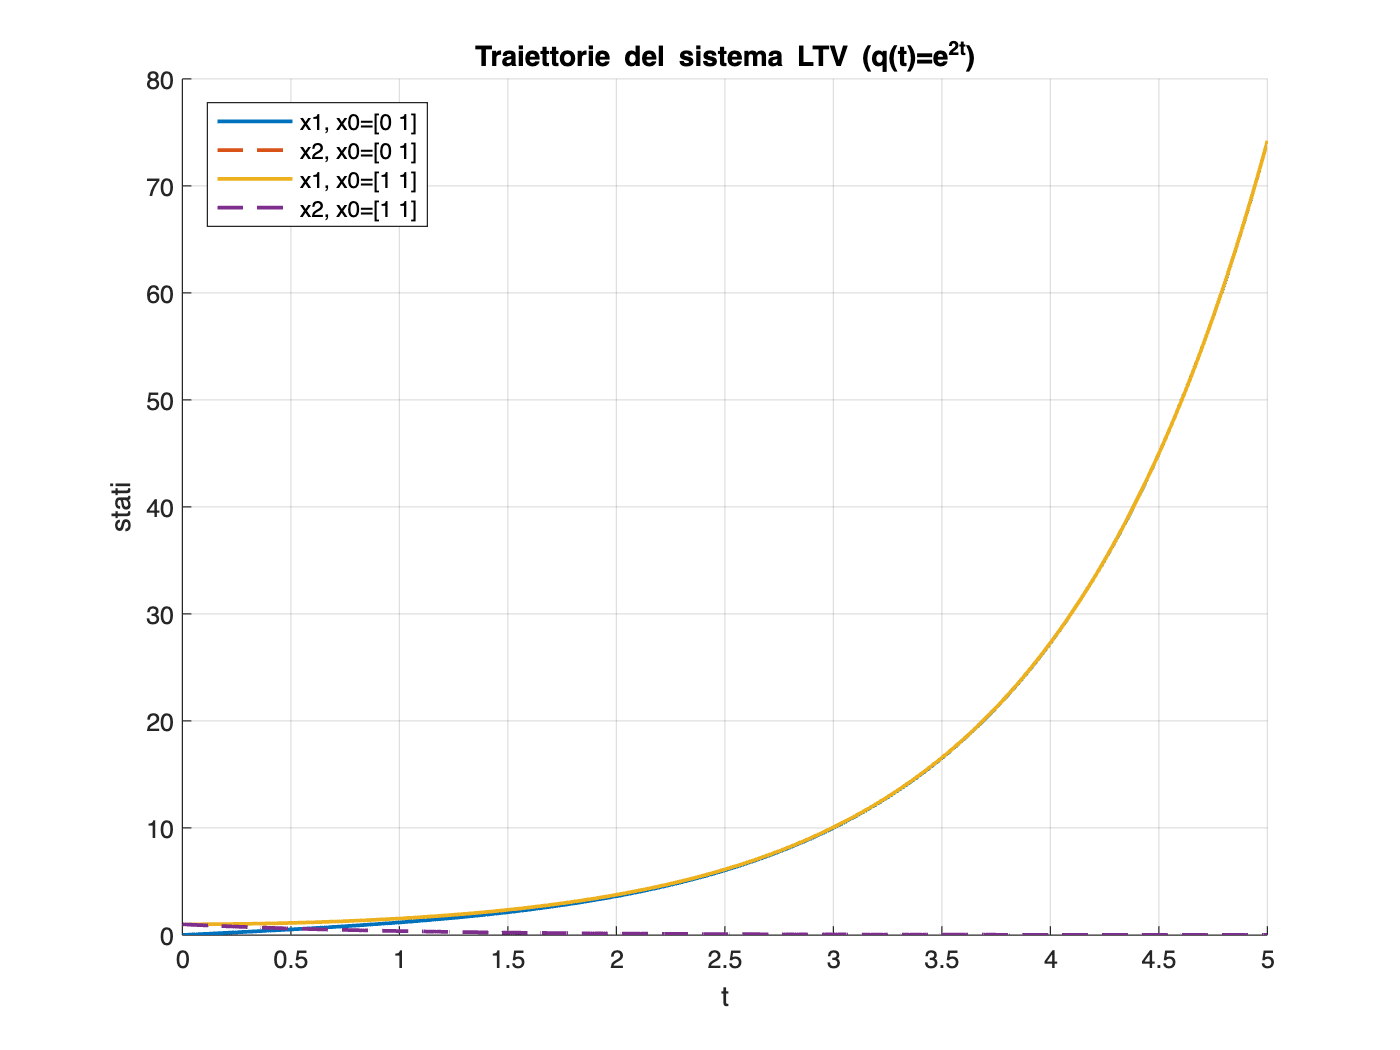

% Pulizia
clearvars; close all; clc;

% Intervallo di simulazione
t = linspace(0,5,501); % da 0 a 5 secondi

% Definizione di q(t)
q = @(tt) exp(2*tt);

% Matrice A(t) come funzione
A_of_t = @(tt) [-1, q(tt); 0, -1];

% RHS per ode45 (sistema non-autonomo)
ltv_rhs = @(tt,x) A_of_t(tt)*x;

% Condizioni iniziali di prova
x0_list = {[0; 1], [1; 1]};

%% Simulazione numerica con ode45
sols = cell(size(x0_list));
for k = 1:length(x0_list)
    [T, X] = ode45(ltv_rhs, t, x0_list{k});
    sols{k}.T = T;
    sols{k}.X = X;
end

%% Grafico delle traiettorie
figure('Name','Traiettorie sistema LTV','NumberTitle','off');
hold on; grid on;
colors = lines(length(sols));
for k = 1:length(sols)
    plot(sols{k}.T, sols{k}.X(:,1), '-', 'DisplayName', sprintf('x1, x0=[%g %g]', x0_list{k}), 'LineWidth', 1.5);
    plot(sols{k}.T, sols{k}.X(:,2), '--', 'DisplayName', sprintf('x2, x0=[%g %g]', x0_list{k}), 'LineWidth', 1.5);
end
xlabel('t');
ylabel('stati');
title('Traiettorie del sistema LTV (q(t)=e^{2t})');
legend('Location','best');
hold off;

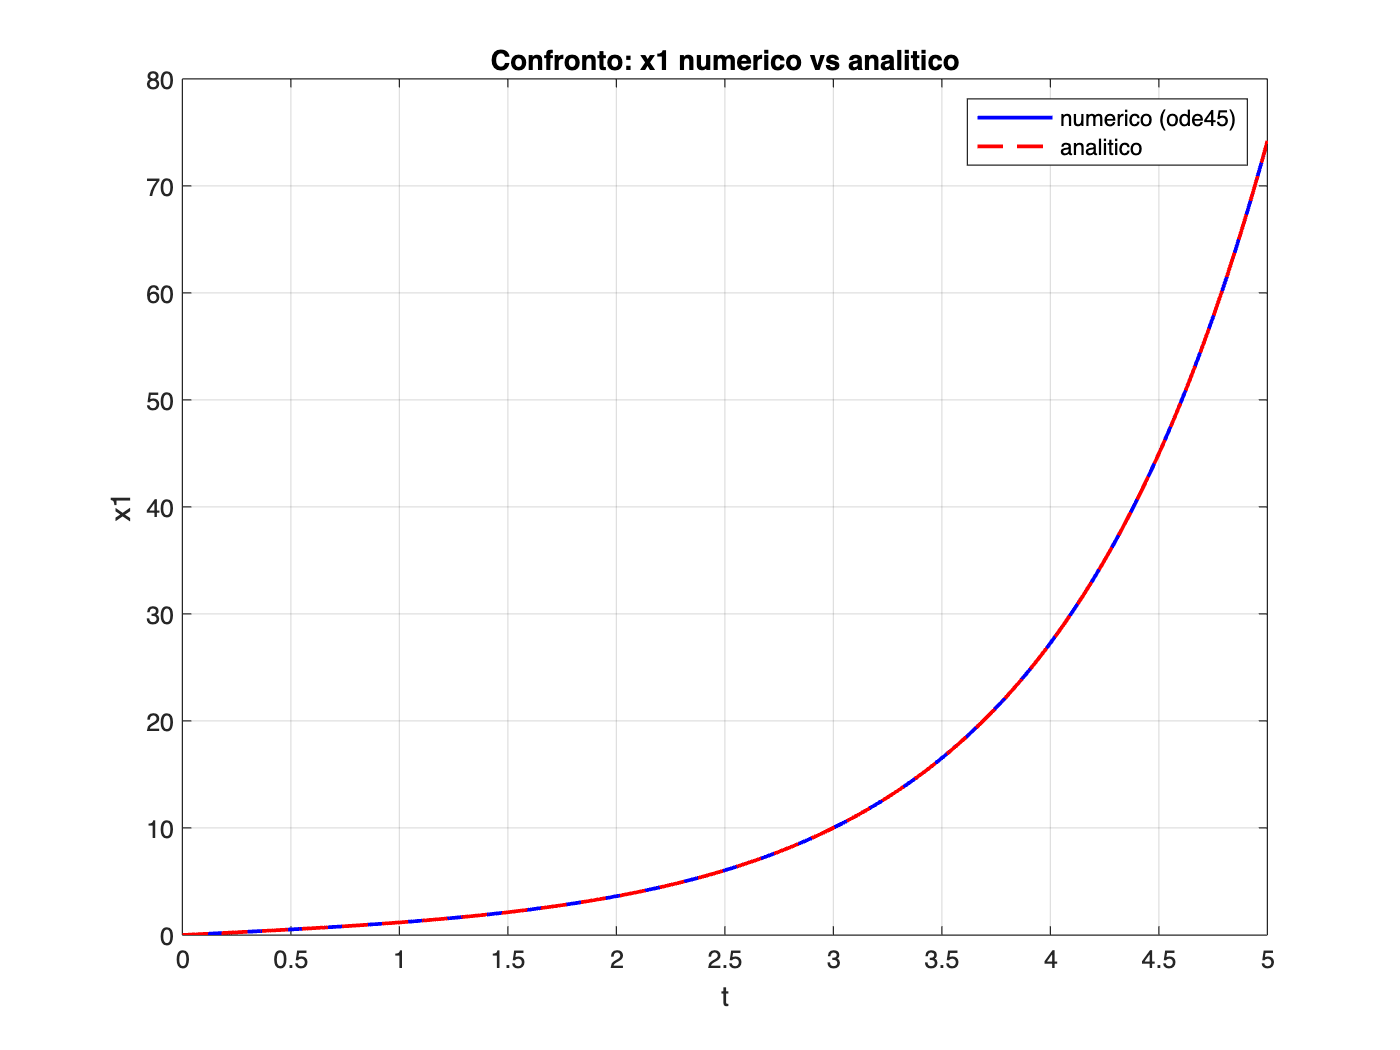


%% Verifica della soluzione analitica (confronto numerico)
% Soluzione analitica per x2 e x1 (dato x1(0), x2(0))
analytic = @(t, x0) deal( x0(2).*exp(-t), ... % x2(t)
    x0(1).*exp(-t) + (x0(2)/2).*(exp(t) - exp(-t)) ); % x1(t)

% Confronto per la prima condizione iniziale
x0 = x0_list{1};
x2_an = x0(2)*exp(-t);
x1_an = x0(1)*exp(-t) + (x0(2)/2).*(exp(t)-exp(-t));

% Plot confronto x1 numerico vs analitico per la prima condizione
figure('Name','Confronto numerico vs analitico per x1','NumberTitle','off');
plot(t, sols{1}.X(:,1), 'b-', 'LineWidth', 1.5); hold on;
plot(t, x1_an, 'r--', 'LineWidth', 1.5);
xlabel('t'); ylabel('x1');
legend('numerico (ode45)','analitico');
title('Confronto: x1 numerico vs analitico');
grid on;